# Render 3-D Audio on Headphones

Modify the 3-D audio image of a sound file by filtering it through a head-related transfer function (HRTF). Set the location of the sound source by specifying the desired azimuth and elevation.

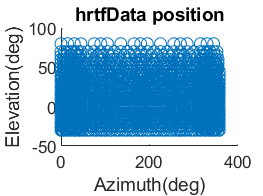

load 'ReferenceHRTF.mat' hrtfData sourcePosition
load rightIR_us.mat rightIR
load leftIR_us.mat leftIR
hrtfData = permute(double(hrtfData),[2,3,1]);

sourcePosition = sourcePosition(:,[1,2]);
figure
scatter(sourcePosition(:,1), sourcePosition(:,2));
title('hrtfData position');
xlabel('Azimuth(deg)');
ylabel('Elevation(deg)');

Calculate the head-related impulse response (HRIR) using the VBAP algorithm at a desired source position. Separate the output, `interpolatedIR`, into the impulse responses for the left and right ears.

desiredAz = 0;
desiredEl = -90;
desiredPosition = [mod(-desiredAz+360,360) desiredEl];

interpolatedIR  = interpolateHRTF(hrtfData,sourcePosition,desiredPosition,"Algorithm","Bilinear");
% interpolatedIR = bilinear_func(hrtfData, sourcePosition, desiredPosition);

leftIRR = squeeze(interpolatedIR(:,1,:))';
rightIRR = squeeze(interpolatedIR(:,2,:))';
dF = 48000/length(leftIR);
figure
plot(dF*[-length(leftIR)/2 : length(leftIR)/2-1],fftshift(mag2db(abs(fft(leftIRR))))-fftshift(mag2db(abs(fft(leftIR)))));
hold

Current plot held


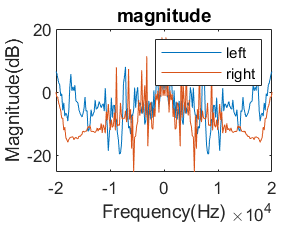

plot(dF*[-length(leftIR)/2 : length(leftIR)/2-1],fftshift(mag2db(abs(fft(rightIRR))))-fftshift(mag2db(abs(fft(rightIR)))));
xlim([-20000,20000]);
legend('left','right');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');
title('magnitude');

figure
plot(dF*[-length(leftIR)/2 : length(leftIR)/2-1],fftshift(unwrap(angle(fft(leftIRR))))-fftshift(unwrap(angle(fft(leftIR)))));
hold

Current plot held


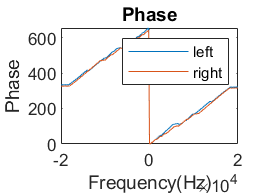

plot(dF*[-length(leftIR)/2 : length(leftIR)/2-1],fftshift(unwrap(angle(fft(rightIRR))))-fftshift(unwrap(angle(fft(rightIR)))));
xlim([-20000,20000]);
legend('left','right');
xlabel('Frequency(Hz)');
ylabel('Phase');
title('Phase');

Create a `dsp.AudioFileReader` object to read in a file frame by frame. Create an `audioDeviceWriter` object to play audio to your sound card frame by frame. Create two `dsp.FIRFilter` objects and specify the filter coefficients using the head-related transfer function interpolated impulse responses.

fileReader = dsp.AudioFileReader('RockDrums-48-stereo-11secs.mp3');
deviceWriter = audioDeviceWriter('SampleRate',fileReader.SampleRate);

leftFilter = dsp.FIRFilter('Numerator',leftIR);
rightFilter = dsp.FIRFilter('Numerator',rightIR);

In an audio stream loop:

- Read in a frame of audio data.

- Feed the stereo audio data through the left and right HRIR filters, respectively.

- Concatenate the left and right channels and write the audio to your output device.

while ~isDone(fileReader)
    audioIn = fileReader();
    
    leftChannel = leftFilter(audioIn(:,1));
    rightChannel = rightFilter(audioIn(:,2));
%     leftChannel = audioIn(:,1);
%     rightChannel = audioIn(:,2);
    output = [leftChannel,rightChannel];
    deviceWriter(output);
end


As a best practice, release your System objects when complete.

release(deviceWriter)
release(fileReader)

*Copyright 2018 The MathWorks, Inc.*